# **Lab #5 Feedback Stabilization: Stick Balancing**

This lab is based upon the problems in Section 11.1, "Feedback Stabilization: Stick Balancing," in the course text *Computer Explorations in SIGNALS AND SYSTEMS* by Buck, Daniel, Singer.   

This  exercise considers the problem  of  stabiiizing the unstable  system  that governs the balancing of an object like a stick in your hand. 

                                                               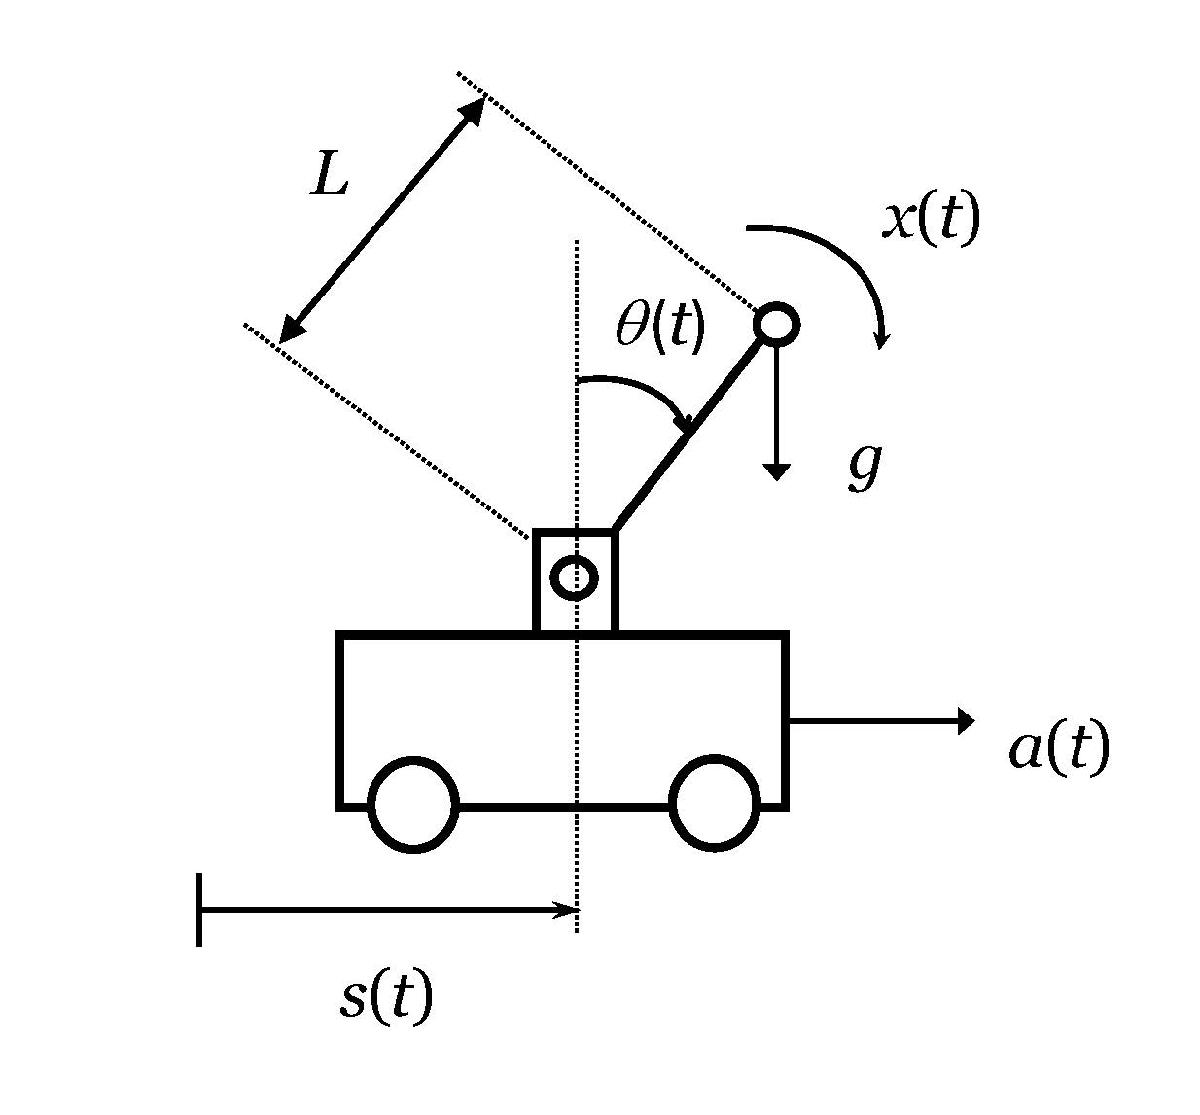

                                                                                      Fig. 1

Consider the systems  shown in Fig. 1.  The cart, whose position is given by $s(t)$, can  move forward or backward. The acceleration of the cart follows as $d^2s/dt^2 = a(t)$  A stick of length $L$ is attached  to the cart with a hinge so that it can only move in the same  direction as the cart. The   position of the stick is given by the angle  $\theta(t)$. Assume   that all  ofthe  mass  of the stick is concentrated  in a ball at the end of the stick. Also shown is an angular acceleration $x(t)$ imparted  on the stick by external forces, such as the wind. In order  to balance  the stick, the  cart  must be moved  with an appropriate  acceleration $a(t)$.

Balancing  forces on the mass along  the direction perpendicular to the rod, the differential equation relating $\theta(t)$,  $a(t)$, and $x(t)$ is

                                   
$$\quad  \quad  \quad \quad L\frac{d^2\theta(t)}{dt^2} = g\sin(\theta(t)) -a(t)\cos(\theta(t)) + Lx(t).$$


This is  not  a linear differential equation. However,  we  can linearize it for small $\theta(t)$ to examine the  dynamics when the stick is nearly  vertical, which is the region of interest when balancing  the  stick.   Using  the small angle  approximations $\sin(\theta(t))\approx \theta(t)$ and $\cos(\theta(t))\approx 1$  for  $|\theta(t)| \ll \pi$, the linearized differential equation governing  the system is

                                   
$$\quad \quad \quad \quad L\frac{d^2\theta(t)}{dt^2} = g\theta(t) -a(t) + Lx(t).$$


**In the numerical problems solved with MATLAB below,  assume that  **$L=1$**m and **$g=9.8$** m/sec**${}^2$**.**

**Task 1**. Assuming  the cart  is statioinary with  zero acceleration, $a(t)=0$, derive  the system function $H(s)$ relating the input (disturbance) $x(t)$ to   the output  $\theta(t)$. Determine the poles and zeros of  the system. Using your result,  explain why the system is unstable.  Use `plotpz` to numerically determine the poles and zeros,  confirming your analysis,  and to make  a pole-zero plot for this system. (The function `plotpz` is included at the end of  this script.)

The equation, given a(t) = 0 is now L d2(Theta)/dt^2 = gTheta(t) + Lx(t)

Laplace:

Ls^2 = gTheta(s) + LX(s)

so H(s) = Theta/ X = L / (Ls^2 -g) = 1/ s^2 - g/L    -->. poles at s = +- sqrt(g/L), no finite zeros 

One of the poles is in the right-half plane which is why the ssystem is unstable, (the small change in Theta will grow over time)

L = 1; 
g = 9.8;
num = 1;
den = [1 0 -g/L]

den =     1.0000         0   -9.8000


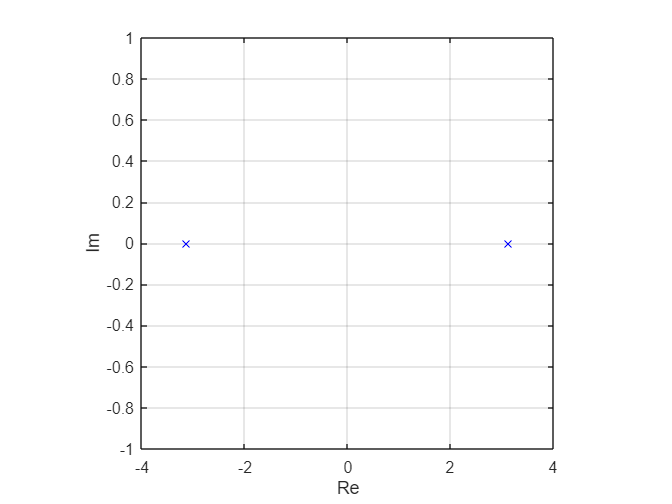


figure;
[p, z] = plotpz(num, den);

disp('Zeros:');

Zeros:


disp(z);
disp('Poles:');

Poles:


disp(p)

    3.1305
   -3.1305



**Task  2.** Consider stabilizing the system  with proportional (P) feedback using an acceleration of  the cart which is proportional to the angle  $\theta(t)$, i.e., $a(t)=k \theta(t)$. Determine the system function for the system  with proportional feedback. Let $k$ range  over the values k=linspace(0,25,11). Determine the maximum magnitude of the real part $MaxR$ and the maximum imaginary part $MaxI$ among all of the poles for all $k$ in this range.  

now, since a(t) = kTheta(t)

Ld2T/dt^2 = gT - kT + Lx  (Theta is represented as T and functionsall in terms of t, reduced for simiplicity and clarity)

so now, applying the same tactice as last time:

H(s) = L / (Ls^2 - (g-k))

        = 1 / (s^2 - ( g- k )/L

s = +-  sqrt((g-k)/L)  so if k > g, system is stable

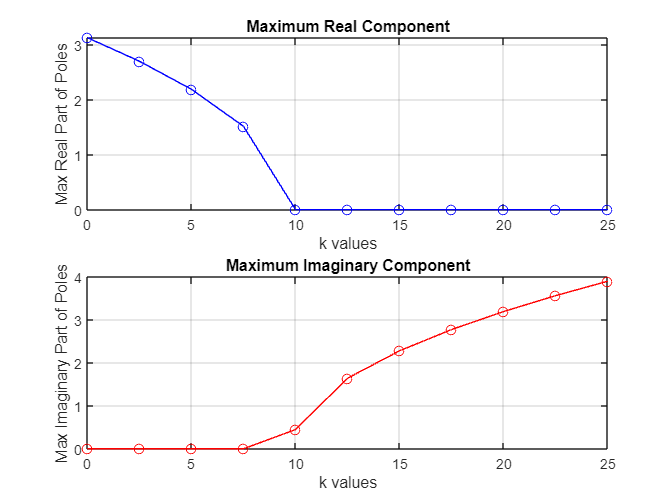

k_values = linspace(0, 25, 11); % Range of k values
max_real = zeros(size(k_values));
max_imag = zeros(size(k_values));

for i = 1:length(k_values)
    k = k_values(i);
    den = [1 0 -(g-k)/L];
    poles = roots(den);
    
    max_real(i) = max(real(poles)); % Max real part
    max_imag(i) = max(abs(imag(poles))); % Max imaginary part
end

% Plot results
figure;
subplot(2,1,1);
plot(k_values, max_real, 'b-o');
xlabel('k values');
ylabel('Max Real Part of Poles');
title('Maximum Real Component');
grid on;

subplot(2,1,2);
plot(k_values, max_imag, 'r-o');
xlabel('k values');
ylabel('Max Imaginary Part of Poles');
title('Maximum Imaginary Component');
grid on;

**Task 3.** Modify plotpz by commenting out the statements setting `MaxR` and `MaxI` . Add statements setting the values of `MaxR` and `MaxI`  to the integer ceiling of $MaxR$ and $MaxI$ found  in Task 2.  Now use plotpz in a `for` loop to plot the pole locations for the system using  proportional feedback for all values in `k` in a single  pole-zero plot..  

here we can see the poles change to the Im axis at k = 10 onward

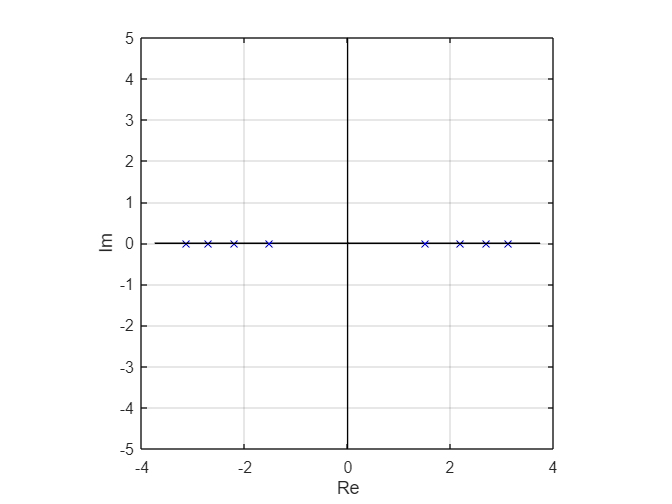

figure;
for i = 1:4
    k = k_values(i);
    den = [1 0 -(g-k)/L];
    [p, z] = plotpz(1, den);
    hold on;

end
hold off;

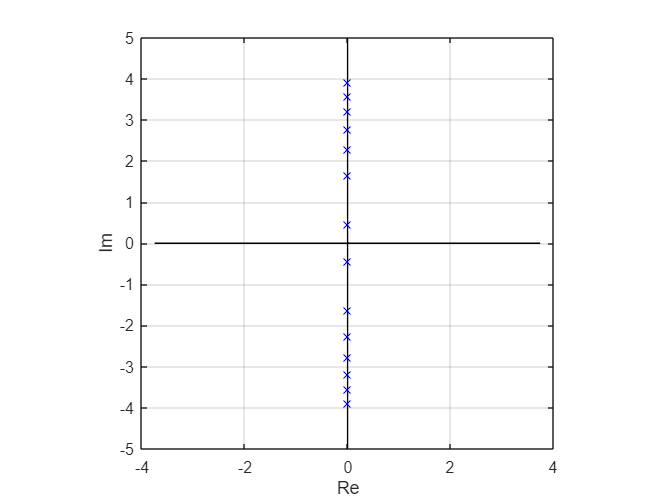

figure;
for i = 5:length(k_values)
    k = k_values(i);
    den = [1 0 -(g-k)/L];
    [p, z] = plotpz(1, den);
    hold on;


end
hold off;

**Task 4.** Using the result of Task 3,  determine if the system can be stabilized using only proportional feedback. Explain your answer.  Find the smallest and largest values of  $k$ in the array `k` such that the stick  location will oscillate back  and  forth indefinitely when $x(t)=\delta(t)$. Explain your answer.

The system can be stabilized using only proportional feedback. As we can see above, for all values of k greater than g, the roots are purely imaginary, this means the system will have to oscilate if it is based on imaginary roots which means it cannot grow exponentially or continuously (meaning the system can be stabilized)

For the sytem to oscillate indefinetly, we need imaginary roots to create the purely imaginary (and oscillated) transfer, 

so smallest is 10 and largest is 25 (from the array) (becuase those are the minimum and maximum imaginary root values for those values of k given by the graph above)

**Task 5.** Use  impulse with the values of $k$ from Task 4 to simulate the impulse response of the corresponding proportional feedback  system over the time  interval `t=linspace(0,10,100)`, storing the simulated values for  $\theta(t)$ in  arrays `th1 `and `th2. `Make  a  plot showing` th1 `and` th2 `over the time interval` t, `and label the plot  appropriately`.   `

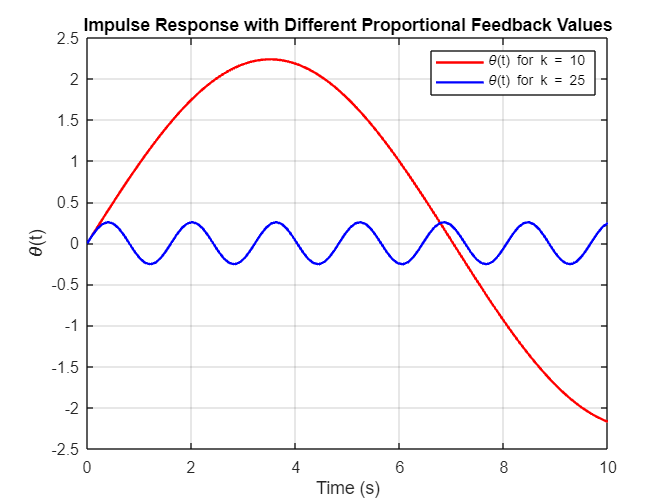

 %don't mind the variable names, I had to debug for a bit and left them
 %this way
L = 1;
g = 9.8;
t = linspace(0, 10, 100);

k_unstable = 10;  
k_stable = 25;  

alpha_unstable = sqrt((g-k_unstable)/L);
th1 = sinh(alpha_unstable * t) / alpha_unstable;

omega_stable = sqrt((k_stable-g)/L);
th2 = sin(omega_stable * t) / omega_stable;

figure;
plot(t, th1, 'r', 'LineWidth', 1.5); 
hold on;
plot(t, th2, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('\theta(t)');
title('Impulse Response with Different Proportional Feedback Values');
legend({['\theta(t) for k = ', num2str(k_unstable), ], ...
        ['\theta(t) for k = ', num2str(k_stable), ]});
grid on;

Next, you will consider   using proportional-plus-derivative (PD) feedback  to  stabilize the  system, i.e., feedback of  the form

                                                      
$$a(t)=k_1 \theta(t) + k_2 \frac{d\theta(t)}{dt}.$$


**Task 6.**  Analytically determine the system function for  the system with PD feedback. Show that you can find  values  for $k_1$ and $k_2$ so that the  system function has  the form 

                                                    
$$H(s) = \frac{1}{s^2+8s+16}.$$


(This corresponds to a critically dampled second-order system with damping ratio $\zeta=1$ and undampled natural frequency $\omega_n=4$ rad/sec.) 

We can start the same way we started at the beggining of this lab, by noting H(S) is T/X which from the PD feedback equation above gives:

L d^2T/dt^2 = gT + L(a) + Lx

Ls^2T- LsTk_2 - (g+Lk_1)T = LX

H(s)  =  1/ (Ls^2 - Lsk_2 - (g + Lk_1))

         = 1/ [s^2 - sk_2 - (g+Lk_1)/L]

so all we need to to find constant values to satisfy the equation above

k_2 = -8   , (g+Lk_1)/L = -16

**Task 7.  **Restore the original  calculation of` MaxI` and `MaxR` in `plotpz`. Use plotpz to plot  a pole-zero   diagram for the system using the values for $k_1$ and $k_2$ you found in Task 6. What is  the order of the poles and zeros?

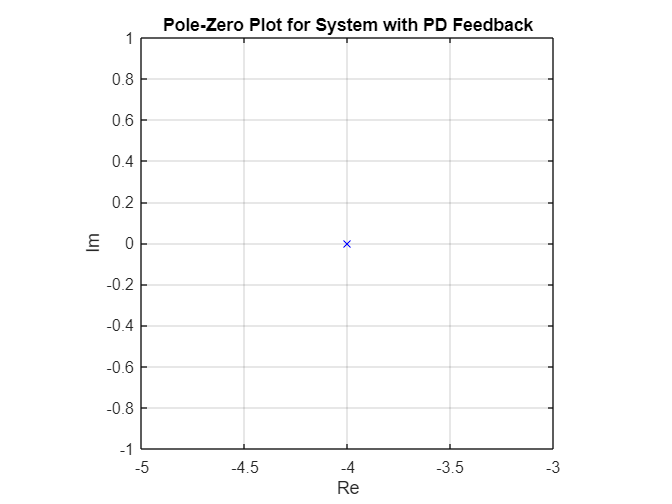

L = 1;
g = 9.8;
omega0 = 4;
k2 = -2*omega0;
k1 = -L*omega0^2 - g;

num = 1;
den = [1 -k2 -(g+k1)/L];

figure;
[p, z] = plotpz(num, den);
title('Pole-Zero Plot for System with PD Feedback');

disp('Zeros:');

Zeros:


disp(z);
disp('Poles:');

Poles:


disp(p);

    -4
    -4



There are no zeros and one pole at -4 which makes perfect sense when looking at the above system function form which can also be written as 

H(s) = 1 / (s + 4)^2

**Task 8.  **Use ` impulse `to simulate the impulse  response of the system with PD feedback  from Task 6 over the time  interval` t=linspace(0,10,100), `storing the  simulated  values for $\theta(t)$ `in th3. `Make a plot showing` th3 `over the time interval` t, `and label the plot  appropriately`. `Determine the impulse response of the causal system $H(s)$analytically and confirm that it matches your simulation result.  Does  the system with PD feedback stabilize the stick in response to an impulse disturbance`? `

` H(s) = 1/(s+4)^2`

`h(s) = t * exp(-4t)* u(t)        (lap table)`

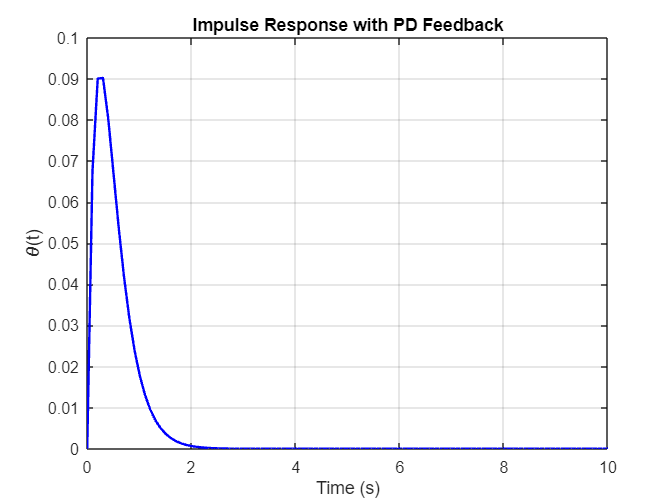

L = 1;
g = 9.8;
omega0 = 4;
k2 = -2*omega0;
k1 = -L*omega0^2 - g;

t = linspace(0, 10, 100);
th3 = t.*exp(-omega0*t); 

figure;
plot(t, th3, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('\theta(t)');
title('Impulse Response with PD Feedback');
grid on;

The system does stabilize the stick (pretty quickly too) as seen by the graph

**Task  9. **Create a disturbance $x(t)$ that takes the value 1 over the time interval $0\leq t\leq 5$ using `x=[ones(1,50) zeros(1,50)]. `Use `lsim `to simulate the response  of the system with PD feedback from Task 6  to the input $x(t)$ over  the time  interval `t,` storing the resulting simulated values for $\theta(t)$ in` th4`. Make a plot showing` th4 `over the time interval` t, `and label the plot  appropriately`. `Does the system recover from this disturbance and stabilize the stick? 

lsim wasnt working so I found another way to represent

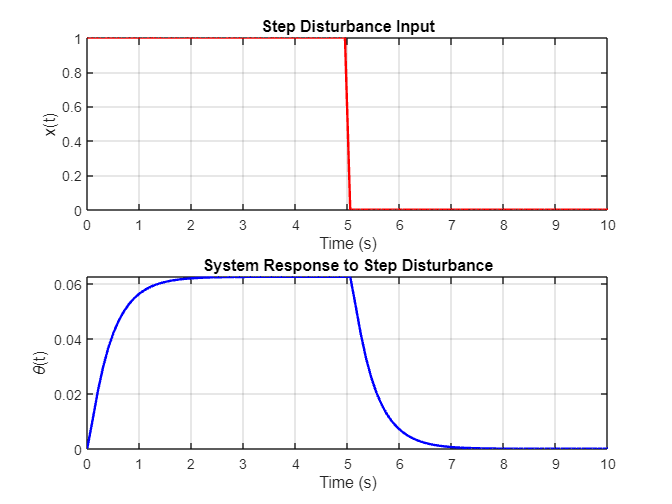


L = 1;
g = 9.8;
omega0 = 4;
k2 = -2*omega0;
k1 = -L*omega0^2 - g;


t = linspace(0, 10, 100);
dt = t(2) - t(1);

% Step input for half the time
x = [ones(1,50) zeros(1,50)];

% Initialize the output and state variables
th4 = zeros(size(t));
theta = 0;  % Initial angle
dtheta = 0; % Initial angular velocity

% Manually simulate the system using numerical integration
for i = 1:length(t)-1
    
    % d^2θ/dt^2 = (g+k1)/L * θ + k2 * dθ/dt + x(t)
    d2theta = (g+k1)/L * theta + k2 * dtheta + x(i);
    
    dtheta = dtheta + d2theta * dt;
    theta = theta + dtheta * dt;
    th4(i+1) = theta;
end


figure;
subplot(2,1,1);
plot(t, x, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('x(t)');
title('Step Disturbance Input');
grid on;

subplot(2,1,2);
plot(t, th4, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('\theta(t)');
title('System Response to Step Disturbance');
grid on;

The system does recover from the disturbance as seen from theta going back to 0. 

**Task 10. **Create a *random* disturbance $x(t)$ over  the time interval   $0\leq t\leq 5$ using `x=[randn(1,50) zeros(1,50)]`. Use `lsim `to simulate the response  of the system with PD feedback from Task 6  to the input $x(t)$ over  the time  interval `t, `storing the resulting simulated values for $\theta(t)$ in` th5`. Make a plot showing` th5 `over the time interval` t, `and label the plot  appropriately`. `Does the system recover from the random disturbance and stabilize the stick?

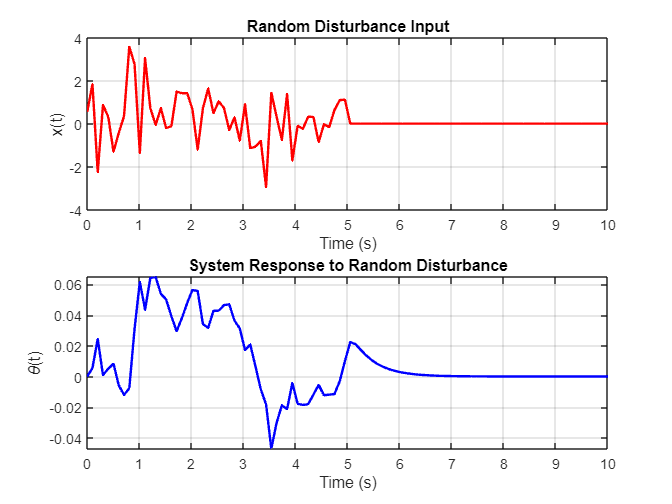

%note: same method as last time, same system, different input

rng(0);

x = [randn(1,50) zeros(1,50)];


th5 = zeros(size(t));
theta = 0;  % Initial angle
dtheta = 0; % Initial angular velocity

% Manually simulate the system using numerical integration
for i = 1:length(t)-1
    % d^2θ/dt^2 = (g+k1)/L * θ + k2 * dθ/dt + x(t)
    d2theta = (g+k1)/L * theta + k2 * dtheta + x(i);
    dtheta = dtheta + d2theta * dt;
    theta = theta + dtheta * dt;
    th5(i+1) = theta;
end
figure;
subplot(2,1,1);
plot(t, x, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('x(t)');
title('Random Disturbance Input');
grid on;

subplot(2,1,2);
plot(t, th5, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('\theta(t)');
title('System Response to Random Disturbance');
grid on;

The system clearly recovers, very similarly to last time, and stabalizes after the random imput stops. 

**Task 11.  **Plot the acceleration of the cart $a(t)$ used  to balance the stick in response to the  disturbance in Task 10.  Since the feedback is PD, you will have  to use both $\theta(t)$ and $\frac{d\theta(t)}{dt}$  to calculate  $a(t)$. You can approximate  $\frac{d\theta(t)}{dt}$ from $\theta(t)$ by using a backwards Euler approximation based on the limiting definiton of  the derivative

                                                            
$$\frac{d\theta(t)}{dt} = \lim_{\Delta t \rightarrow 0} \frac{\theta(t)-\theta(t-\Delta t)}{\Delta t}$$


which translates in the sampled domain  to  `dth[n]=(th[n]-th[n-1])/dt`, where `dt` is the time separation of the  values in `t. `For a cart of mass  $m$, the force required  to generate acceleration $a(t)$ would be $F=ma(t)$.

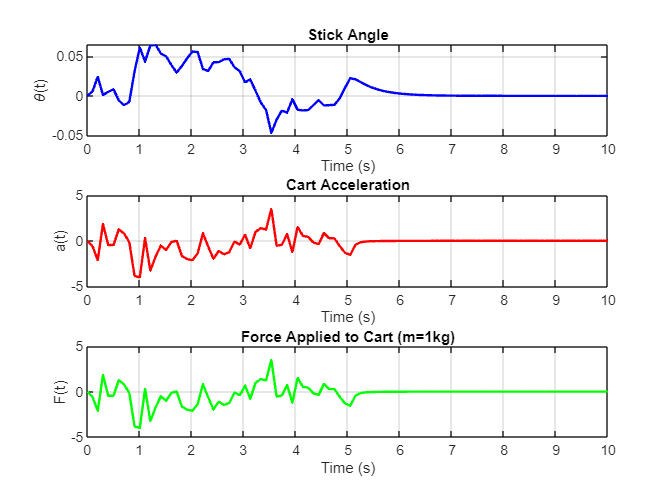


dth5 = zeros(size(t));
dth5(1) = 0; 
a_cart = zeros(size(t));
theta = 0; 
dtheta = 0; 

for i = 1:length(t)-1
    dth5(i) = dtheta;
    % a using PD feedback
    a_cart(i) = k1 * theta + k2 * dtheta;
    % d^2θ/dt^2 = (g+k1)/L * θ + k2 * dθ/dt + x(t)
    d2theta = (g+k1)/L * theta + k2 * dtheta + x(i);
    dtheta = dtheta + d2theta * dt;
    theta = theta + dtheta * dt;
    
    th5(i+1) = theta;
end


dth5(end) = dtheta;
a_cart(end) = k1 * theta + k2 * dtheta;

% force
m_cart = 1;
F_cart = m_cart * a_cart;

figure;
subplot(3,1,1);
plot(t, th5, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('\theta(t)');
title('Stick Angle');
grid on;

subplot(3,1,2);
plot(t, a_cart, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('a(t)');
title('Cart Acceleration');
grid on;

subplot(3,1,3);
plot(t, F_cart, 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('F(t)');
title('Force Applied to Cart (m=1kg)');
grid on;

0;
%---------------------------------------------------
%
%  function [h]=impulse(num,den,t)
%  
%  t   = row vector of time samples where impulse response is computed
%  num = numerator of rational system function  (row vector of high-order to 
%  low-order coefficients)
%  den = denominator of rational system function  (row vector of high-order to 
%  low-order coefficients)
%   
%  
%--------------------------------------------------


function [p,z]=plotpz(b,a)  

%---------------------------------------------------------------
% copyright 1996, 2001, by John Buck, Michael Daniel, and Andrew Singer.
% For use with the textbook "Computer Explorations in Signals and
% Systems using MATLAB", Prentice Hall, 1997, 2002.
%---------------------------------------------------------------

p=roots(a); % determine poles
z=roots(b); % determine zeros
p=p(:); % make into column vector
z=z(:); % make into column vector

% For plotting, determine maximum real part of all poles, zeros, and 1
MaxR= max(abs(real([p;  z; 1])));
%MaxR = 3;
% For plotting, determine maximum imaginary part of all poles, zeros, and j
MaxI= max(abs(imag([p; z; j])));
%MaxI = 4;
%MaxR= 
%MaxI= 
%why hold on

plot(1.25*[-MaxR MaxR],[0 0],'k')     % Plot the real axis
plot([0 0],1.25*[-MaxI MaxI],'k')     % Plot the imag axis
plot(real(z),imag(z),'ro')   % Plot zeros
plot(real(p),imag(p),'bx')   % Plot poles
xlabel('Re');
ylabel('Im');
%
box on
axis('square');                      % Make square aspect ratio
grid on
%hold off
end
